clc;
clear all;
close all;

%% system parameters
Sysparam = struct();

Sysparam.Nt = 256;
Sysparam.Nr = 4;
Sysparam.Ns = 4;
Sysparam.fc = 300*1e9;%carrier frequency 
Sysparam.f = 30*1e9; %bandwidth 
Sysparam.K = 129;  %number of sub-carriers
Sysparam.M = 16; %number of TTDs for each RF chain
Sysparam.N = Sysparam.Nt/Sysparam.M; %number of PSs for each TTD
Sysparam.L = 1 ; % number of paths equals to number of RF chains
%Sysparam.Nrf=Sysparam.L;
Sysparam.tmax = 330e-12;% maximum time-delay value
% compute discrete time-delay values
Sysparam.Q = 128; % number of fixed TTD element 
Sysparam.T = Sysparam.tmax*(0:1:Sysparam.Q-1)/(Sysparam.Q-1);
%% Sub-carrier frequencies
for k =1:Sysparam.K 
    Sysparam.F(k,1) = Sysparam.fc +(Sysparam.f/Sysparam.K)*(k-1-(Sysparam.K-1)/2); % sub-carrier frequency
end 
% relative frequencies
Sysparam.xi = Sysparam.F/Sysparam.fc; 

%% simulation parameters
Simparam = struct();

%Simparam.phi = [0.62;0.62;0.62;0.62];
%Simparam.phi = 0.2*pi*ones(Sysparam.L,1); %AoD;
Simparam.psi = pi*rand(Sysparam.L,1)-0.5*pi; %AoA;
Simparam.P = -20:5:15;% transmit power in dB
Simparam.Rho = 10.^(Simparam.P/10); %transmit power
Simparam.Niter = 50; %channel realizations

%Simparam.phi = pi*rand(Sysparam.L,1)-0.5*pi %AoD;
Simparam.phi = 0.295*pi*ones(Sysparam.L,1)%AoD;

Simparam = struct with fields:
      psi: -0.5231
        P: [-20 -15 -10 -5 0 5 10 15]
      Rho: [0.0100 0.0316 0.1000 0.3162 1 3.1623 10 31.6228]
    Niter: 50
      phi: 0.9268


%Simparam.phi = pi*((0.5-0.2951)*rand(Sysparam.L,1)+0.2951) %AoD;
SpatialDirection = sin(Simparam.phi)

SpatialDirection = 0.7997

%Generate wideband channel
H = WidebandChannel(Sysparam,Simparam);

[G1,G2k,x2,t2] = fixPSdesignTTD(Sysparam,Simparam); %Tan design
[PS,TTD,x,t] = jointPSandTTD(Sysparam, Simparam); % joint delay and phase precoding

tic
[S,F2k,D,Loss] = DynamicSubarray(Sysparam,Simparam,H); %Dynamic subarray method
toc

Elapsed time is 43.296173 seconds.


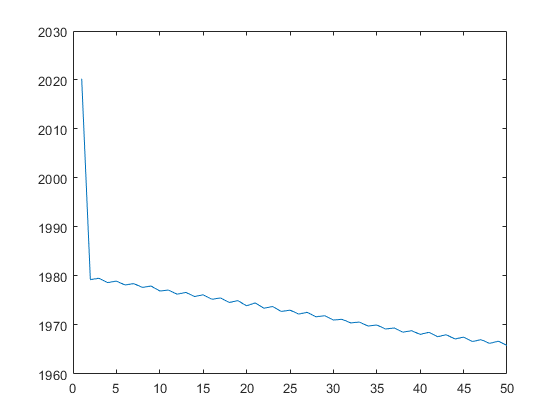

plot(1:length(Loss),Loss)

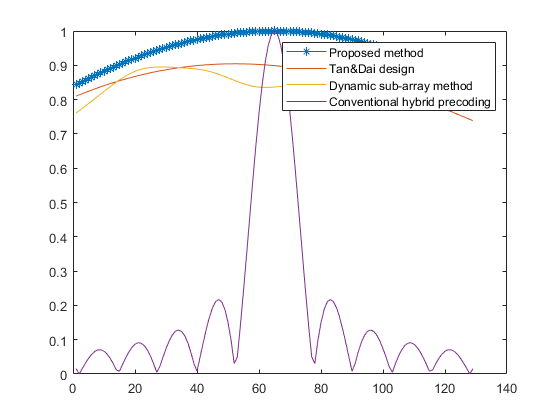

for l = 1:Sysparam.L
    a(:,l) = arrayResponse(sin(Simparam.phi(l)),Sysparam.Nt);
    for k = 1:Sysparam.K
         b(:,k,l) = arrayResponse(Sysparam.xi(k)*sin(Simparam.phi(l)),Sysparam.Nt);
         arrayGain(k,l) = abs(a(:,l)'*b(:,k,l));
         Compensated1(k,l) = abs((PS*TTD(:,l,k))'*b(:,k,l));
         Compensated2(k,l) = abs((G1*G2k(:,l,k))'*b(:,k,l));          
         Compensated3(k,l) = abs((S*F2k(:,l,k))'*b(:,k,l))/sqrt(Sysparam.Nt);
    end
end
% plot(1:Sysparam.K,Compensated,'-*',1:Sysparam.K,Compensated2,1:Sysparam.K,arrayGain)
% legend('Proposed method','Tan&Dai design','Conventional hybrid precoding')
plot(1:Sysparam.K,Compensated1,'-*',1:Sysparam.K,Compensated2,1:Sysparam.K,Compensated3,1:Sysparam.K,arrayGain)
legend('Proposed method','Tan&Dai design','Dynamic sub-array method','Conventional hybrid precoding')

%compute the average array gain
AverageGain1 = sum(Compensated1)/Sysparam.K

AverageGain1 = 0.9458

AverageGain2 = sum(Compensated2)/Sysparam.K

AverageGain2 = 0.8565

AverageGain3 = sum(Compensated3)/Sysparam.K

AverageGain3 = 0.8631